# MATLAB

# Image-Based Defect Detection for Manufacturing Inspection

Team Members:

Christian Loriega

Carlos Tapia

Destiny Aguillon

# Abstract

    We've created a hybrid manufacturing inspection system for screw components using classical image processing and transfer learning. Classical image processing generates interpretable defect evidence and measurable features, while a ResNet-18 AI classifier produces the primary PASS or FAIL decision. The system is evaluated using image batch testing, confusion matrices, yield statistics, defect rates, and robustness testing under simulated lighting, blur, and noise variations.

    Modern manufacturing inspection systems must provide both reliable classification decisions and understandable evidence explaining why a component was accepted or rejected. Although deep-learning models can achieve strong classification performance, their predictions may be difficult for engineers and operators to interpret. In comparison, classical image-processing methods can generate measurable and traceable evidence, but they may be sensitive to variations in lighting, texture, orientation, and image quality.

    Our motivation stemmed from the need to combine the strengths of both approaches. The ResNet-18 classifier provides the primary PASS or FAIL decision, while the classical image-processing pipeline identifies suspicious geometric features and produces evidence overlays and numerical measurements. This hybrid approach improves transparency, supports debugging, and provides useful information for validating inspection decisions.

    Our team specifically targeted screw components because they can contain subtle manufacturing defects, including tip damage, scratches, and thread damage. Developing an automated and repeatable inspection pipeline demonstrates how computer vision and artificial intelligence can support manufacturing quality control.

# a. Problem Definition and Proposed Solution

**Problem Statement: **

    The objective of this project is to create an automated image-based inspection system using MATLAB, that identifies defective screw components. The system must classify each inspected part as PASS or FAIL while also generating interpretable visual and numerical evidence that explains what the inspection system detected.

**Requirements:**

- Standardize and preprocess each input image.

- Identify and quantify suspicious visual evidence.

- Classify parts as PASS or FAIL using a pretrained neural network.

- Return a classification confidence score.

- Produce evidence overlays and metric data.

- Evaluate performance on a repeatable test dataset.

- Test robustness under brightness, blur, and noise variation.

**Dataset: **MVTec AD - Screw Dataset

**Software: **MATLAB R2026a, Deep Learning Toolbox, Image Processing Toolbox

**Constraints:**

- MVTec AD's training folder only contains good images, indicating further variation may be beneficial for advanced accuracy.

- MVTec AD is relatively small for deep-learning training.

- Images may vary in orientation and brightness, indicating further filtering needed.

**Proposed solution:**

Flow Diagram - 

# b. Project File Organization

# c. Function Reference

    The hybrid inspection system is organized using a modular software architecture using custom dedicated MATLAB functions located in the `/src` directory. Each function performs a specific task within the inspection pipeline, making the system easier to understand, maintain, and extend. The following reference summarizes the purpose, inputs, outputs, and primary operations of each function. Additionally, the functions are organizer in this reference in order of creation and separated by their responsibilities.

**File Location:** `/src`

## `Data Management:`

#### loadDataset

Purpose:

- Loads the MVTec AD dataset into a single MATLAB i**mageDatastore** by combining the training and testing image folders while automatically assigning labels based on folder name.

Key Operations:

- Verifies that the dataset directory exists.

- Reads images from both the train and test folders.

- Automatically assigns labels from the folder names.

- Combines all images into a single imageDatastore for later preprocessing, training, and evaluation.

Input:

- **datasetFolder** - Path to the root directory of the selected MVTec AD object dataset.

Output:

- **imds** - Combined imageDatastore containing all images and their associated labels.

#### exploreDataset

Purpose:

- Provides a visual and statistical overview of the dataset by displaying class distributions, dataset statistics, and randomly selected sample images. This function is intended for exploratory data analysis before model training,

Key Operations:

- Displays the number of images and defect classes.

- Summarizes the number and percentage of images in each class.

- Generates bar graph for class distribution.

- Displays random sample images with corresponding labels.

Input:

- **imds** - MATLAB imageDatastore containing the dataset images and labels.

Output:

- No output variables, simply displays statistics, plots, and sample images.

## Image Preprocessing:

#### preprocessImage

Purpose:

- Standardizes the input image for the hybrid inspection system by resizing it to the network input dimensions and generates both RBG and grayscale versions for AI classification and classical image processing.

Key Operations:

- Resizes input image to 224 x 224 pixels.

- Ensures the image contains three color channels (Red, Green, Blue) for compatibility with ResNet-18.

- Converts to image to grayscale for later classical vision.

Input:

- **inputImage** - Original input image of intended part.

Output: 

- **rgbImage **- Standardized RGB image used for AI classification.

- **grayImage** - Grayscale image used for classical image processing and evidence extraction.

## Classical Vision:

#### detectManipulatedFront

Purpose:

- Detects front-tip defects on a screw image using classical image processing functions and techniques. The function hones in on the screw tip and extracts geometric evidence, evaluates predefined ed inspections rules, and generates both quantitative measurements and a visual inspections overlay. This function implements the 'manipulated_front' defect class from the MVTec AD dataset and serves as the first classical defect detector within the hybrid inspection system.

Key Operations:

- Segments and isolates the screw from the background.

- Aligns and auto-standardizes the screw orientation.

- Identifies the front-tip inspection region and crops it as a region of interest.

- Measures geometric features and describes the screw tips as pixels.

- Applies rule-based inspection thresholds to determine a baseline PASS/FAIL decision.

Input:

- **grayImage** - Preprocessed grayscale image of the screw.

Output:

- **overlay** - Annotated inspection image showing the analyzed tip region and detected evidence.

- **metrics **- Structure containing extracted geometric measurements and rule evaluations results.

- **baselineDecision **- Classical image PASS/FAIL decision based on defined inspection rules.

#### extractEvidence

Purpose:

- Acts as the central evidence extraction module for the classical vision system. It calls the appropriate defect detection algorithm, and returns he corresponding visualization and baseline inspection result.

Key Operations:

- Routes the input image to the appropriate classical defect detector (detectManipulatedFront).

- Returns evidence overlay, extracted measurements, and rule-based inspection decision. 

Input:

- **grayImage **- Preprocessed grayscale image of the screw.

Output:

- **overlay** - Annotated inspection image showing the analyzed tip region and detected evidence.

- **metrics **- Structure containing extracted geometric measurements and rule evaluations results.

- **baselineDecision **- Classical image PASS/FAIL decision based on defined inspection rules.

## AI Classification:

#### classifyPart

Purpose:

- Classifies an input screw image as PASS or FAIL using our trained ResNet-18 transfer learning model. The function preprocesses the image, runs the network prediction, and returns AI's predicted label and confidence in the prediction. The network uses weights learned from ImageNet and fine-tuned during training to recognize manufacturing defects.

Key Operations:

- Utilizes preprocessImage function to preprocess the input image to require the 224 x 224 RGB format for ResNet-18.

- Creates an augmentedImageDatastore compatible with ResNet-18.

- Generates class scores using the trained network.

- Converts class scores into PASS/FAIL label (ex. [0.98 0.02] -> ["PASS" "FAIL]).

- Returns highest class score as prediction confidence.

Input:

- **net** - Trained ResNet-18 network used for PASS/FAIL classification.

- **inputImage** - Original image of the screw to be classified.

Output:

- **aiLabel** - Predicted class label, PASS or FAIL.

- **aiScore** - Highest predicted class score, represents networks confidence score in its decision.

## Hybrid Inspection:

#### inspectPart

Purpose:

- Executes the complete hybrid pipeline for a single input image by combining AI classification with classical image processing. The function returns the final AI inspection result together with evidence extracted from the classical image system.

Key Operations:

- Loads our trained ResNet-18 model using a persistent variable.

- Preprocesses and standardize input image using preprocessImage function

- Performs AI-based PASS/FAIL classification using classifyPart function.

- Extracts classical evidence and geometric evidence using extractEvidence function.

- Returns both AI and classical evidence for a hybrid analysis.

Input:

- **inputImage** - Original image of the part to be inspected.

Output:

- **finalLabel **- Final PASS/FAIL prediction generated by the AI classifier. 

- **confidenceScore** - AI confidence score associated with the prediction. 

- **evidenceOverlay** - Annotated image showing the detected classical evidence. 

- **evidenceMetrics** - Structure containing extracted geometric measurements.

- **baselineDecision** - PASS/FAIL decision produced by the classical inspection pipeline.

## Robustness Testing:

#### applyDistortion

Purpose:

- Applies a specific image distortion to simulate common manufacturing inspection variations. This function is used to evaluate the robustness of the hybrid inspection system under an assortment of imaging conditions.

Key Operation:

- Applies the selected image distortion.

- Supports multiple distinct distortion types through switch-case structure.

- Returns the distorted image.

Input:

- **inputImage** - Original input image to be distorted.

- **distortionType** - Type of distortion to apply (none, brightness, blur, noise)

Output:

- **distortedImage** - Image after applying distortion.

# 1. Dataset Exploration and Organization

## **Task 1**

## **1.1 Dataset Selection**

    The MVTec AD screw dataset was selected because it represents realistic industrial inspection problem involving small geometric and surface defects. The dataset is comprised of **good, manipulated_front, scratch_neck, scratch_head, thread_side, and thread_top classes.**

    A focused subset of the dataset was created by selecting the **good, manipulated_front, and scratch_neck classes.** These classes define the PASS and FAIL categories used throughout the inspection pipeline. These classes were chosen because they are the most representative defects found in screws in manufacturing.

**Inspection Labels:**

PASS - 'good'

FAIL - 'manipulated_front', 'scratch_head', 'scratch_neck', 'thread_side', 'thread_top'

# 1.2 Dataset Preparation

    Dataset preparation takes place in **'A_prepare_data.m'.** The **loadDataset** function imports the images into an imageDatastore with their corresponding labels, while the **exploreDataset** function visualizes the dataset and class distribution. The selected classes (good, manipulated_front, and scratch_neck) are then filtered and converted into binary inspection labels, where good is assigned PASS and the defect classes are assigned FAIL. Finally, the script summarizes the dataset size, shows a montage of images, outputs class distribution via bar graph and table, and provides a PASS-to-FAIL ratio.


Dataset Preparation Summary
Dataset          : MVTec AD
Part Type        : screw
Dataset Location : C:\Users\protu\OneDrive\Desktop\GitHub\Image-Based-Defect-Detection-for-Manufacturing-Inspection\scripts\..\data\MVTec AD\screw
Total Images     : 480
Total Classes    : 6

Complete Dataset Distribution
----------------------------------------
          Label          Count
    _________________    _____

    good                  361 
    manipulated_front      24 
    scratch_head           24 
    scratch_neck           25 
    thread_side            23 
    thread_top             23 

     DATASET SUMMARY

Total Images: 480

Number of Classes: 6

          Label          Count    Percent
    _________________    _____    _______<

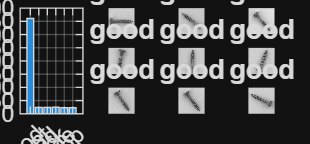


Final Project Scope
PASS Class       : good
FAIL Classes     : manipulated_front, scratch_neck
Focused Images   : 410
Focused Classes  : 3

Focused Dataset Distribution
----------------------------------------
          Label          Count
    _________________    _____

    good                  361 
    manipulated_front      24 
    scratch_neck           25 


Binary Classification Distribution
----------------------------------------
    Label    Count
    _____    _____

    FAIL       49 
    PASS      361 

PASS Images      : 361 (88.05%)
FAIL Images      : 49 (11.95%)
PASS-to-FAIL Ratio: 7.37 to 1


% Task 1 - Dataset Preparation
run("../scripts/A_prepare_data.m")

## 1.3 

# Transfer Learning Results

### Baseline Experiment:

Objective:

- Establish a baseline performance for transfer learning using a pretrained ResNet-18 model with default Adaptive Moment Estimation optimizer settings. The resulting performance metrics provide a benchmark for evaluating the effects of later adjustments.

Training Settings:

- Network: ResNet-18

- Optimizer: Adam

- Learning Rate: 0.001 (Default)

- Epochs: 10

- Batch Size: 32

Results:

- Test Accuracy: 75%

- Training Time: 5 min 44 s

- Final Training Loss: 0.9723

- Final Validation Loss: 0.5474

Observations:

- The training loss generally decreased throughout training, while the validation loss exhibited several fluctuations.

Summary:

- The baseline ResNet-18 model achieved a 75.0% test accuracy using the default Adam learning rate (0.001). While the training loss generally decreased over time, the validation loss showed several fluctuations during training. This experiment establishes a performance benchmark for comparison with later optimization experiments.

Training Graph:

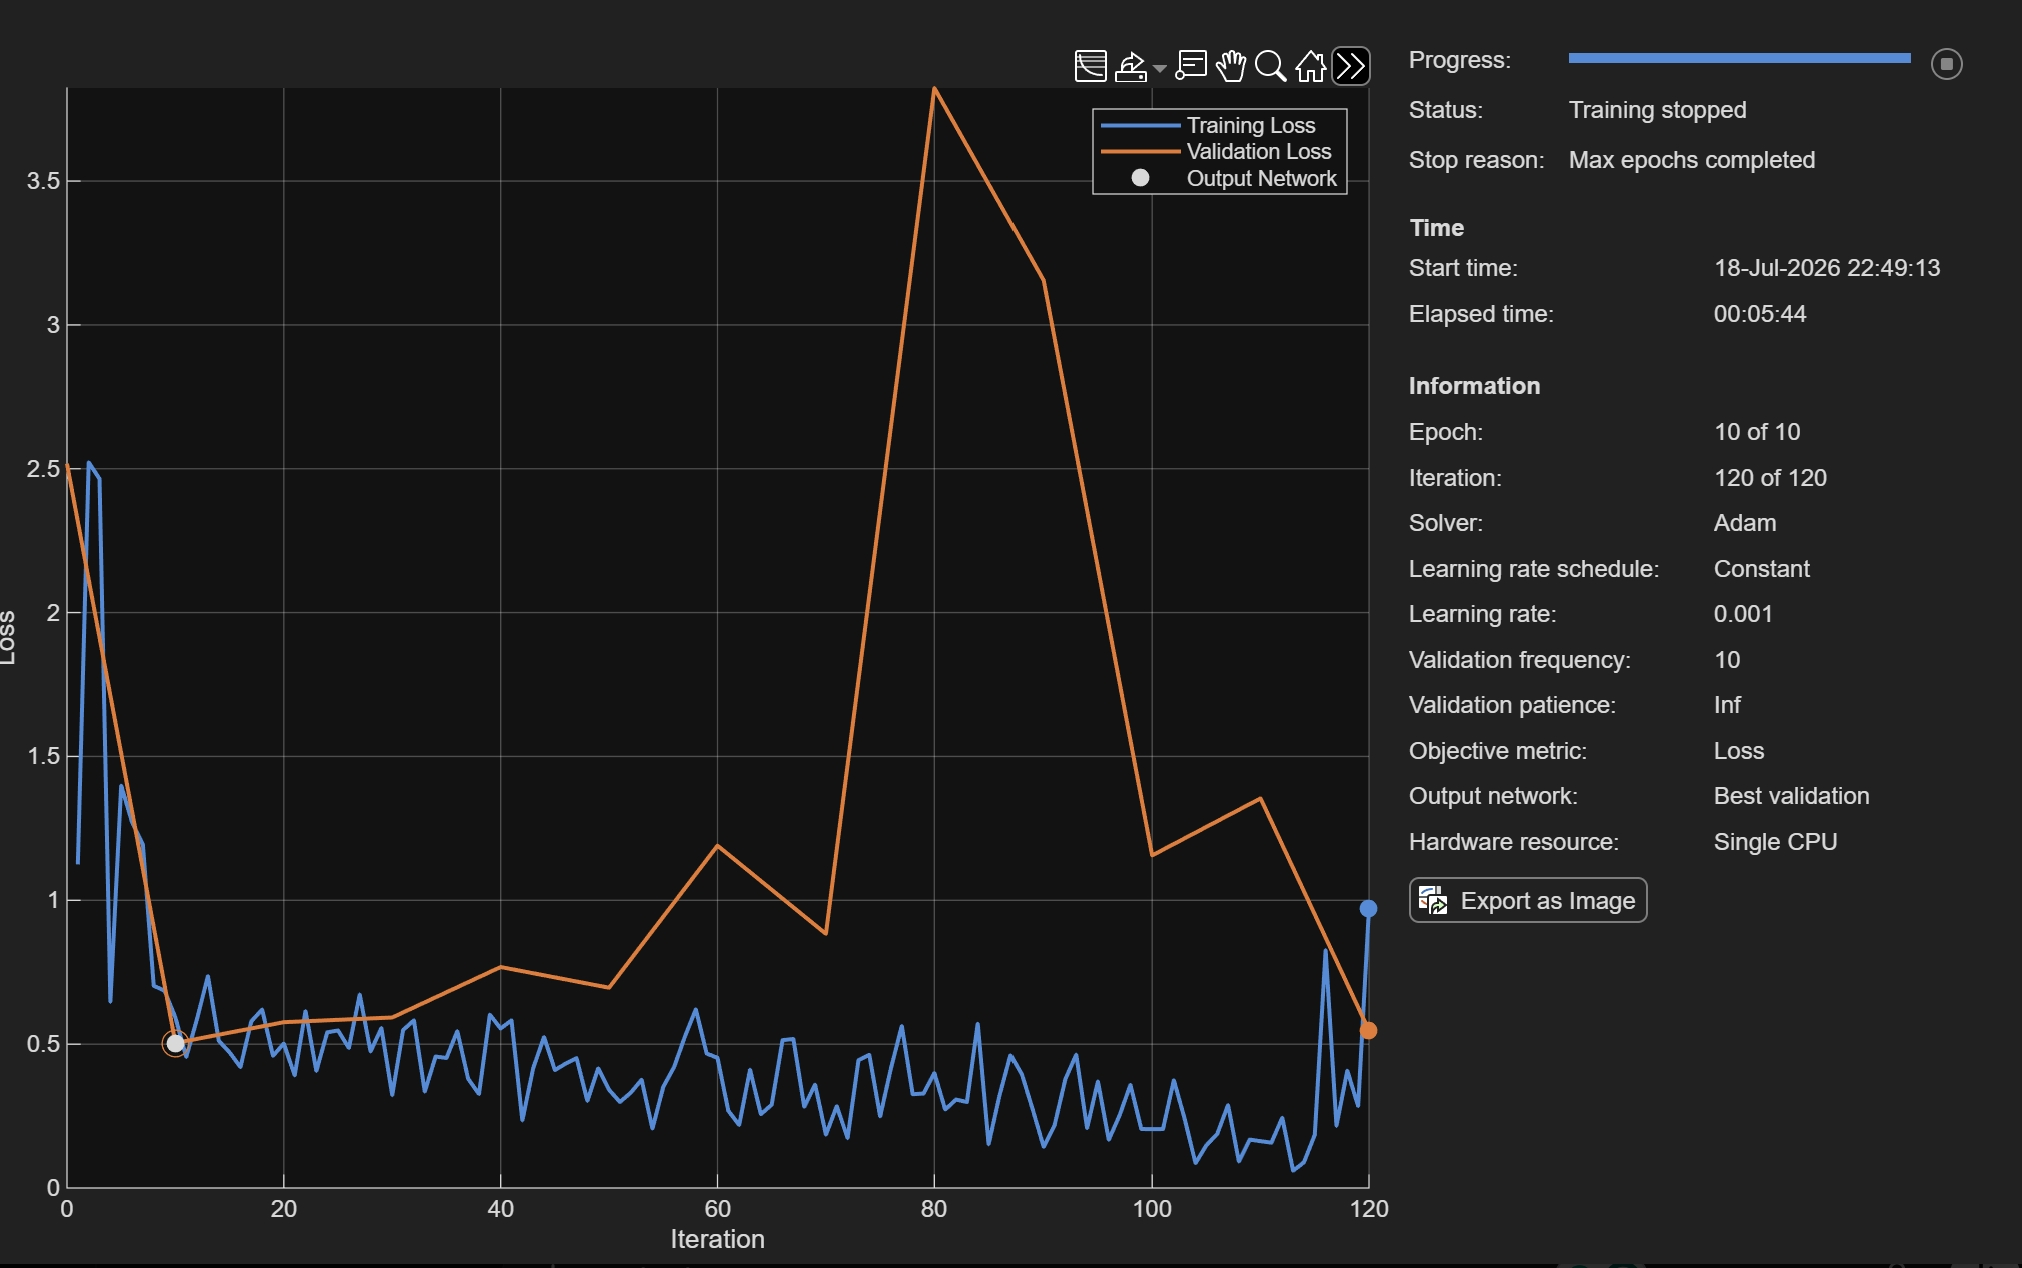

### Experiment 2:

Objective:

- Evaluate whether decreasing the initial learning rate from the default Adam setting to 0.0001 improves the performance of the ResNet-18 transfer learning model.

Training Settings:

- Network: ResNet-18

- Optimizer: Adam

- Learning Rate: 0.0001

- Epochs: 10

- Batch Size: 32

Results:

- Test Accuracy: 87.5%

- Training Time: 4 min 39 s

- Final Training Loss: 0.0839

- Final Validation Loss: 0.3183

Observations:

- A lower learning rate improved generalization and increased defect detection performance from 75% to 87.5%.

- Final training and validation loss are reasonably close indicating this model is well generalized.

Summary:

- By reducing the initial learning rate to 0.0001, the model was able to produce a smoother optimization and classification performance. The training loss steadily decreased through the 10 epochs, indicating that the network continued learning without much instability. While the model's validation loss briefly increased during Epoch 8 and 9, it recovered by the end of the training. This fluctuation was likely due to the validation set only containing 10%, or 48 images of the dataset. Similarly, this peak in the validation loss are observed in both Experiment 2 and the Baseline Experiment, further suggesting this was the cause of the imbalance of the dataset. The final model achieved 87.5% test accuracy, correctly identifying 11 of the 12 defective parts.

Training Graph:

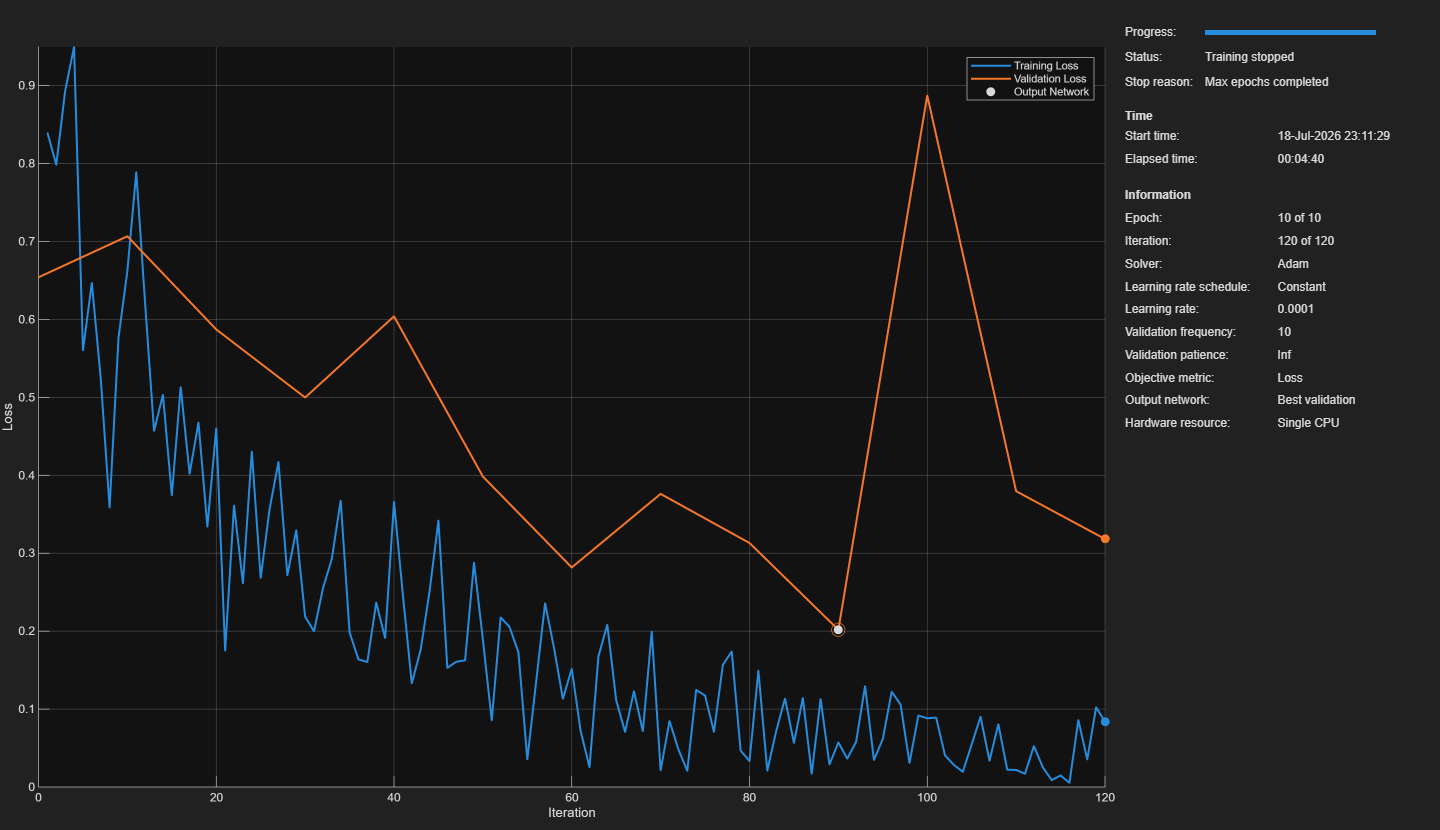

Confusion Matrix:

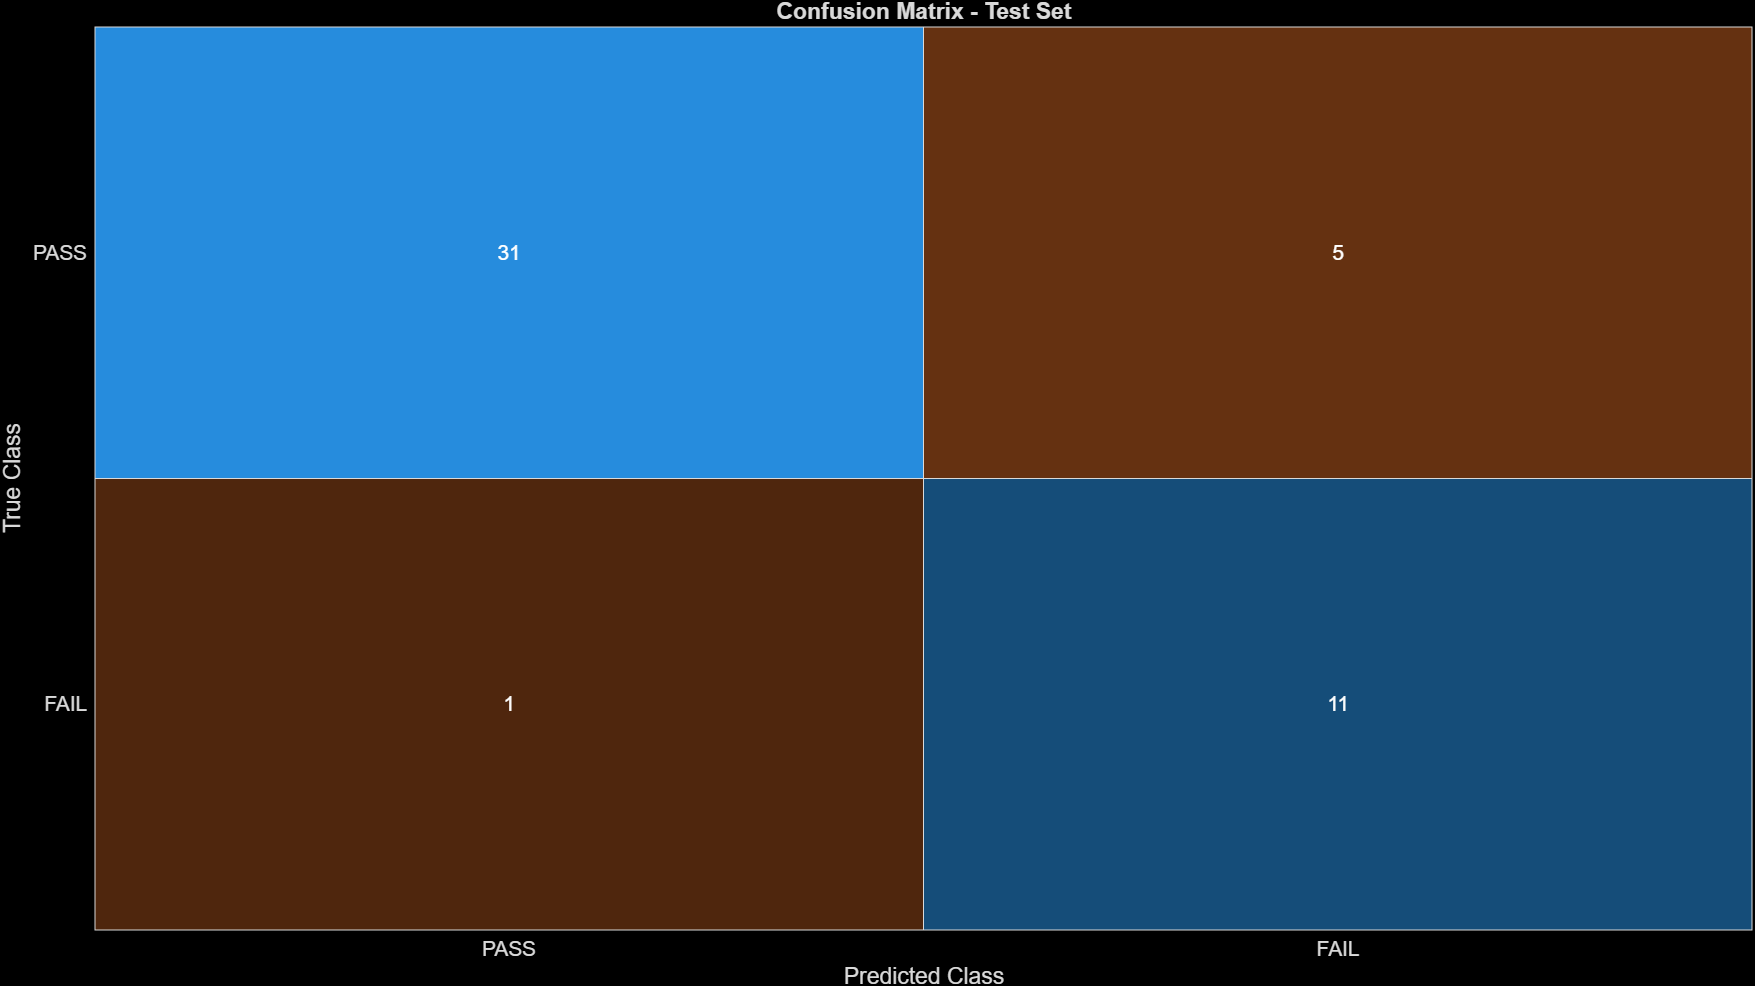

### Experiment 3:

Objective:

- Evaluate whether the number of training epochs from 10 to 20 further improves the performance of the ResNet-18 transfer learning model.

- Monitoring precision, recall, and F1-score as evaluation metrics.

Training Settings:

- Network: ResNet-18

- Optimizer: Adam

- Learning Rate: 0.0001

- Epochs: 20

- Batch Size: 32

Results:

- Test Accuracy: 91.67%

- Training Time: 9 min 41 s

- Final Training Loss: 0.0085479

- Final Validation Loss: 0.15461

- Precision: 0.833

- Recall: 0.833

- F1-score: 0.833

Observations:

- Increasing the number of training epochs from 10 to 20 improved the model's overall classification performance, increasing the test accuracy from 87.5% to 91.67%.

- The training loss steadily decreased throughout training, reaching a final values of 0.0085, indicating that the network continued to learn with the additional epochs.

- While the validation loss fluctuated during several epochs, it decreased to a final value of 0.1546 by the end of training suggesting the model maintained good generalization. 

- The model achieved a precision, recall, and F1-score of 0.833 for the FAIL class demonstrating balanced performance in detecting defective parts while limiting false positive and negatives.

- Approximately double the training time due to double the epochs.

Summary:

- Increasing the maximum number of training epochs from 10 to 20 allowed ResNet-18 to further optimize and learn features after reducing the learning rate. The larger epochs increased the amount of times the network saw the training data set. These results show that the network benefited from additional training time without substantial overfitting.

Training Graph:

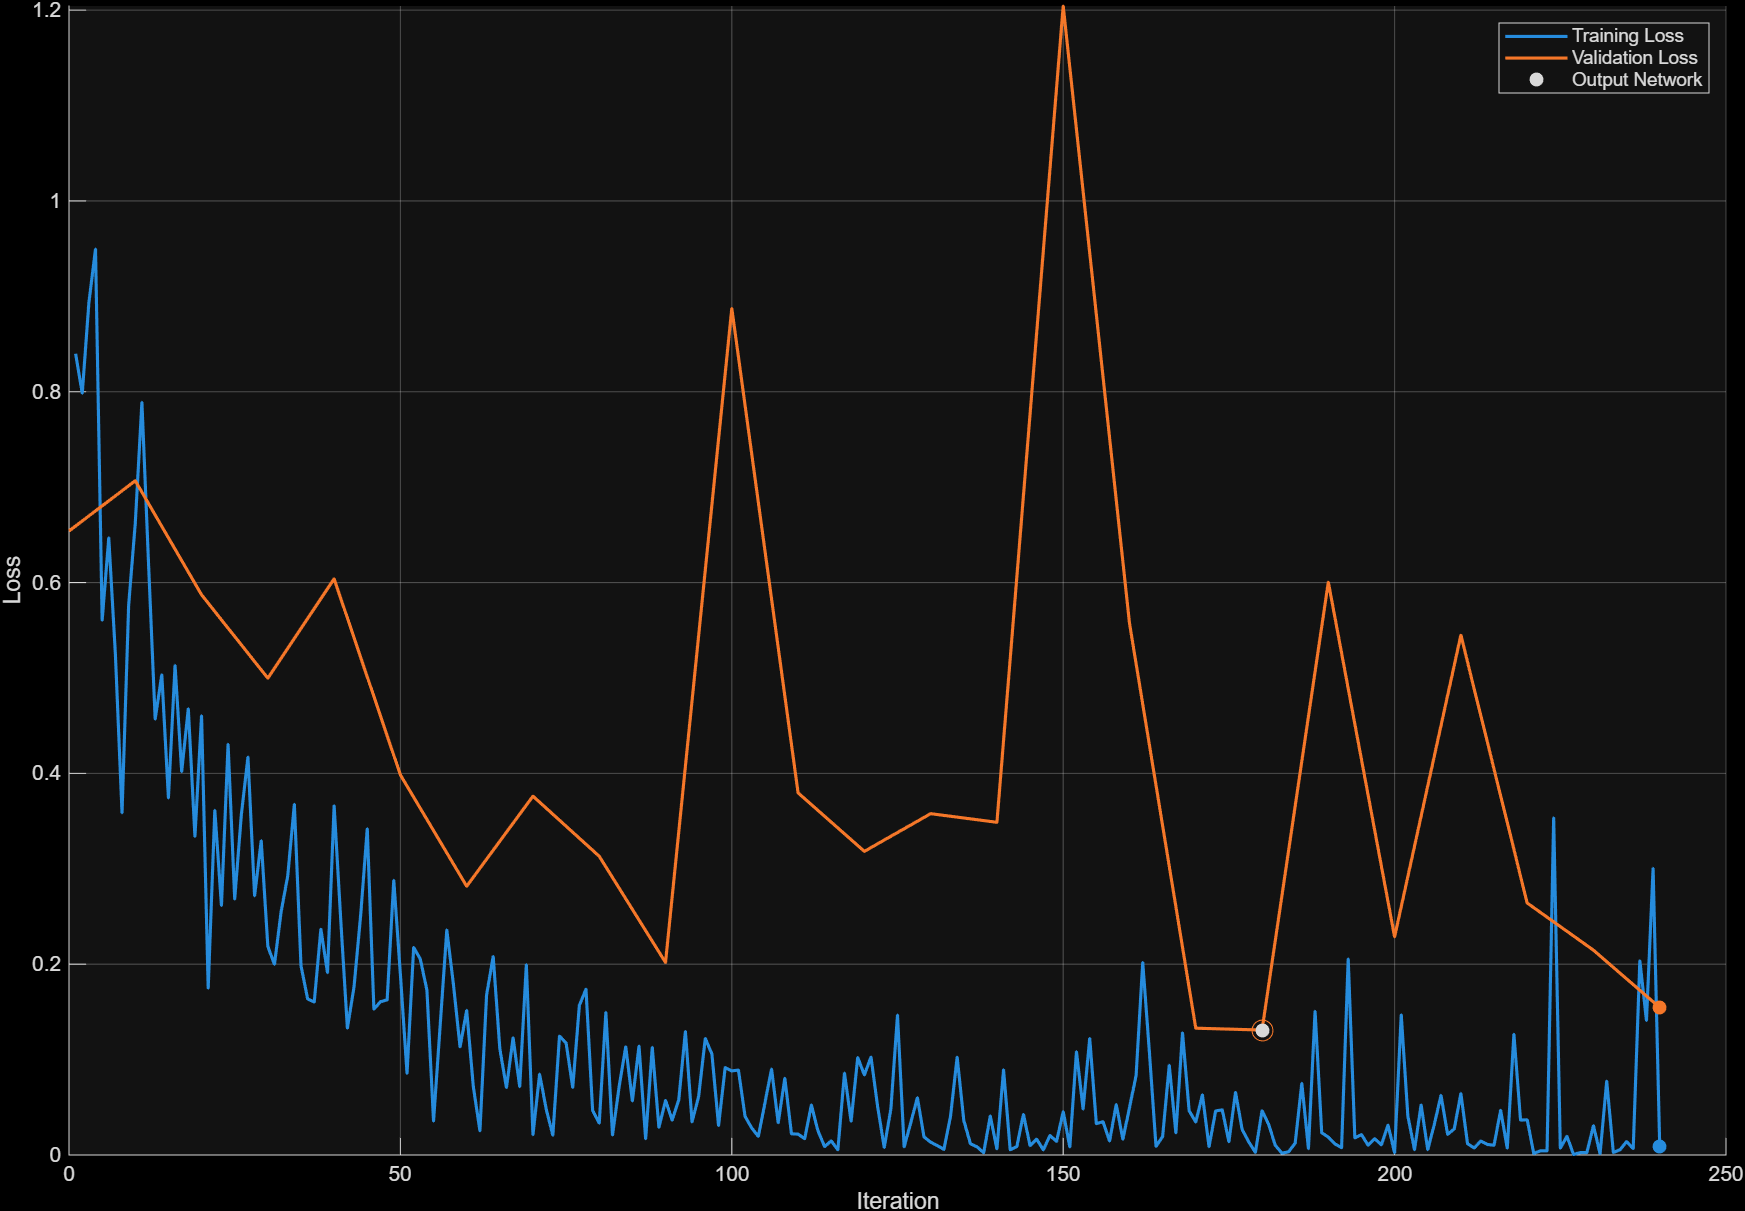

Confusion Matrix:

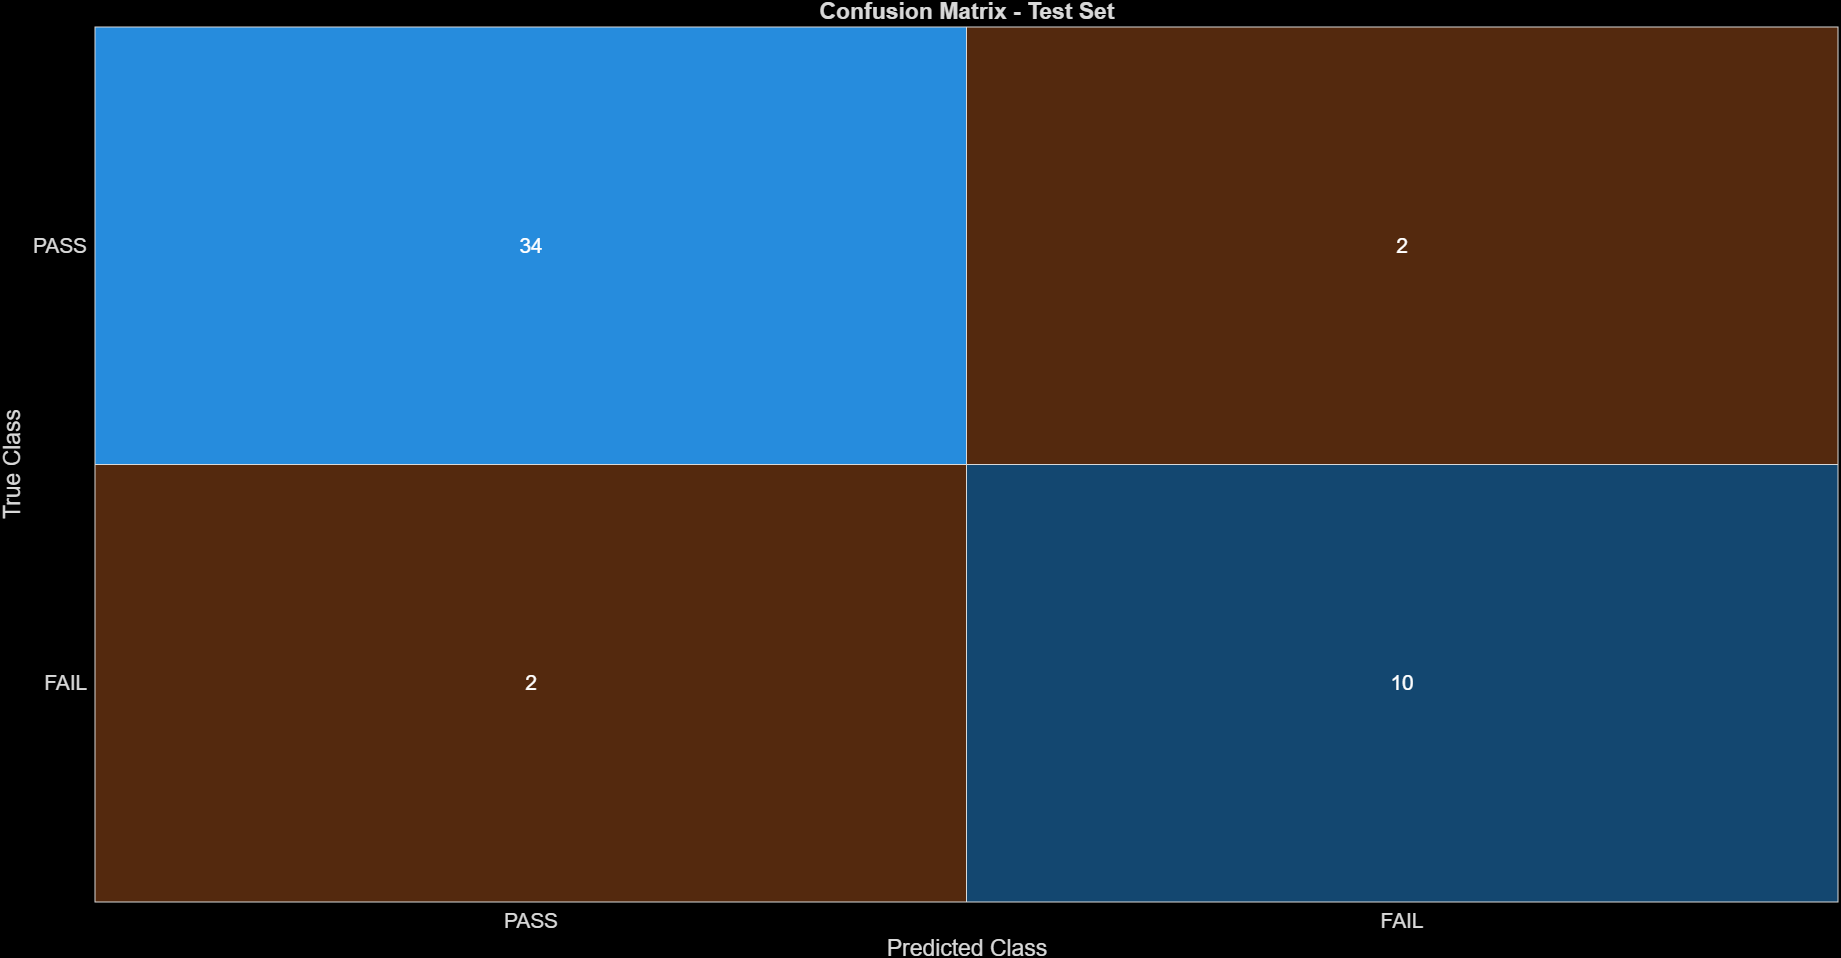

### Experiment 4:

Objective:

- Evaluate whether training ResNet-18 using only the defect categories targeted by the hybrid inspection system (`manipulated_front` and `scratch_neck`) improves classification performance. The original MVTec AD screw dataset was filtered to include only `good`, `manipulated_front`, and `scratch_neck` images before converting the labels to PASS/FAIL. Model performance was evaluated using accuracy, precision, recall, and F1-score.

Training Settings:

- Network: ResNet-18

- Optimizer: Adam

- Learning Rate: 0.0001

- Epochs: 20

- Batch Size: 32

- Dataset**:** Filtered MVTec AD Screw where, PASS: `good, F`AIL: `manipulated_front`, `scratch_neck`

Results:

- Test Accuracy: 95.12%

- Training Time: 7 min 37 s

- Final Training Loss: 0.0010221 

- Final Validation Loss: 0.12881

- Precision: 0.800

- Recall: 0.800

- F1-score: 0.800

Observations:

- Training on a focused dataset improved the overall classification accuracy from 91.67% to 95.12% compared to the previous experiment. By removing defect categories that were not analyzed by the classical inspection system, the AI classifier was trained only on the defects relevant to the final hybrid inspection pipeline.

- The training loss steadily decreased throughout training, reaching a final value of 0.0010, indicating that the network successfully learned the focused classification task. The validation loss also decreased to 0.1288, suggesting good generalization without noticeable overfitting.

- Although the dataset remained imbalanced in terms of good to defective images, the model achieved balanced precision, recall, and F1-score of 0.800 for the FAIL class. The focused model correctly detected four of the five defective images in the held-out test set.

Summary:

- Filtering the training dataset to include only the defect types evaluated by the classical inspection system produced the strongest AI classifier developed during this project. Aligning the AI model with the hybrid system's inspection scope improved classification accuracy while maintaining balanced defect detection performance. This focused ResNet-18 model was selected for integration into the final hybrid inspection system.

Training Graph:

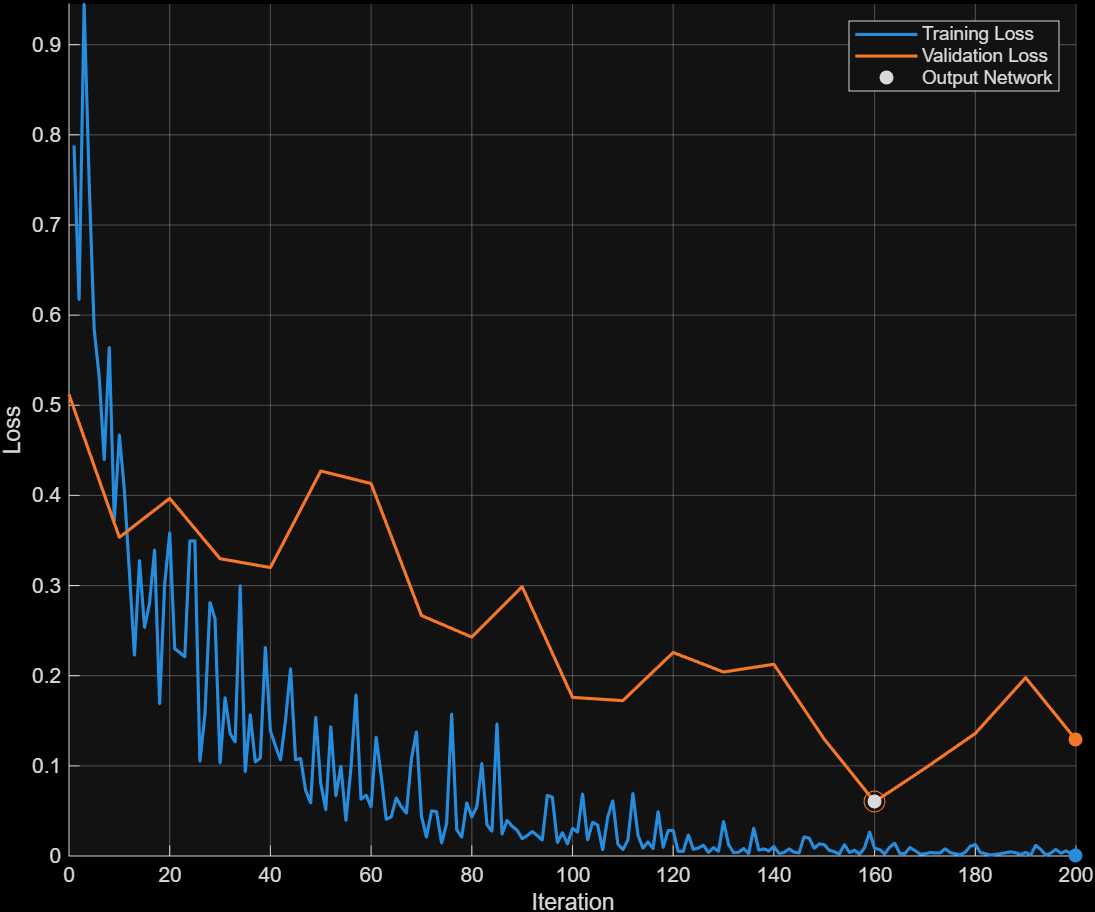

Confusion Matrix:

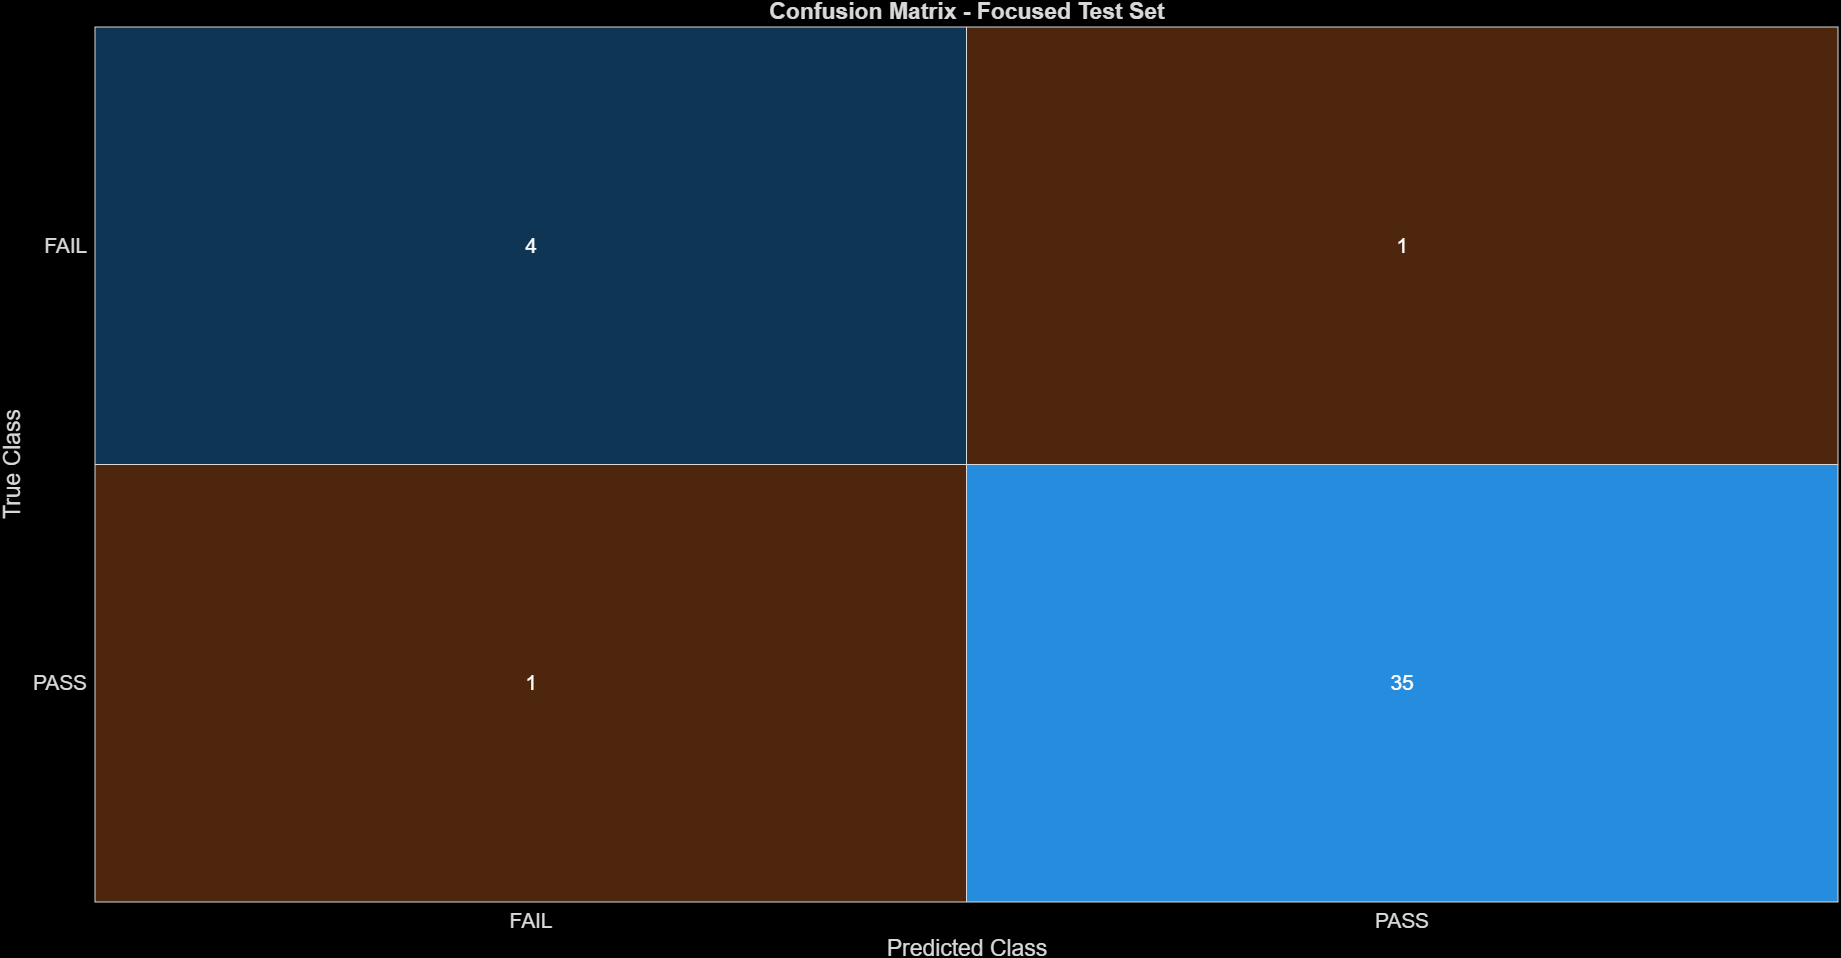

Inspect part 

## Decision Table For Hybrid System